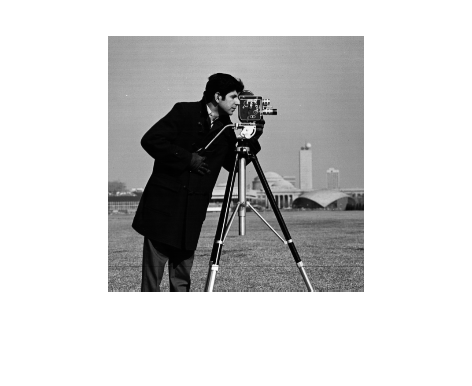

img = imread('Important_files/cameraman.tif');

imshow(img, []);

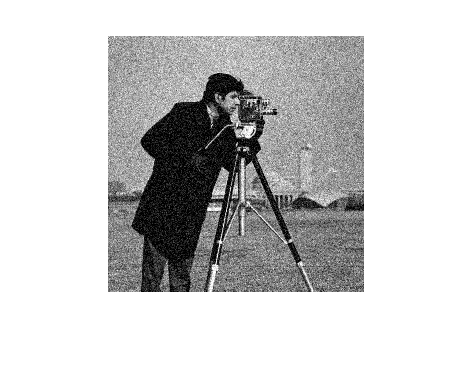


var = 0.01;

noisy_img = imnoise(img,"gaussian", 0, var);

imshow(noisy_img, []);

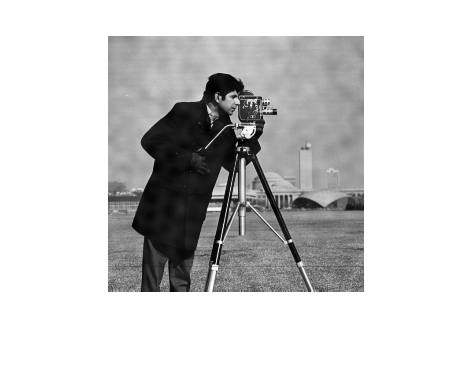


x = 4;

[width, height] = size(img);

large_noise = imresize(normrnd(0, 20, width/x, height/x), x); 

large_noise = imgaussfilt(large_noise, x); 

large_noisy_img = double(img) + large_noise;
imshow(large_noisy_img, []);

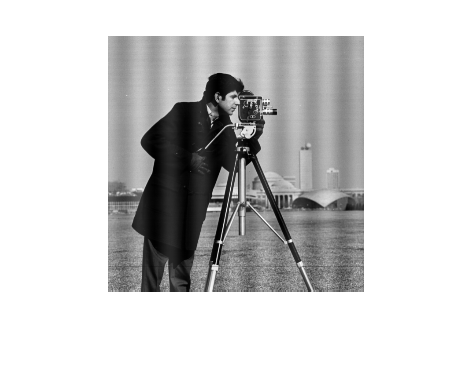


x = linspace(1,width, height);
y = linspace(1,height,height);
[X,Y] = meshgrid(x,y);

wavy_noise = cos(X/5);

wavy_noisy_img = double(img) + 20 * wavy_noise;
imshow(wavy_noisy_img, []);